A = [
0	1.6666666666666667
100	2.3333333333333335
200	7.0
300	11.666666666666666
400	31.0
500	66.33333333333333
600	118.33333333333333
700	195.66666666666666
800	297.3333333333333
900	545.0
1000	1115.3333333333333
1100	2790.0
1200	3899.0
1300	5662.666666666667
1400	9164.333333333334
1500	10508.0
1600	14803.666666666666    
];

J = [
    0	0.0
100	1.6666666666666667
200	6.666666666666667
300	8.666666666666666
400	20.666666666666668
500	43.0
600	71.66666666666667
700	114.66666666666667
800	175.66666666666666
900	271.6666666666667
1000	339.6666666666667
1100	463.6666666666667
1200	613.3333333333334
1300	754.6666666666666
1400	981.3333333333334
1500	1171.6666666666667
1600	1428.6666666666667
1700	1716.0
1800	2010.0
1900	2376.0
];

csvwrite('measurementApache.csv', A);
csvwrite('measurementJama.csv', J);

ls = LeastSquare;
ls.A = A(:,1);
ls.b = A(:,2);
resultVector = ls.solveLeastSquare(3);

start least square
Elapsed time is 0.000047 seconds.
Elapsed time is 0.000217 seconds.


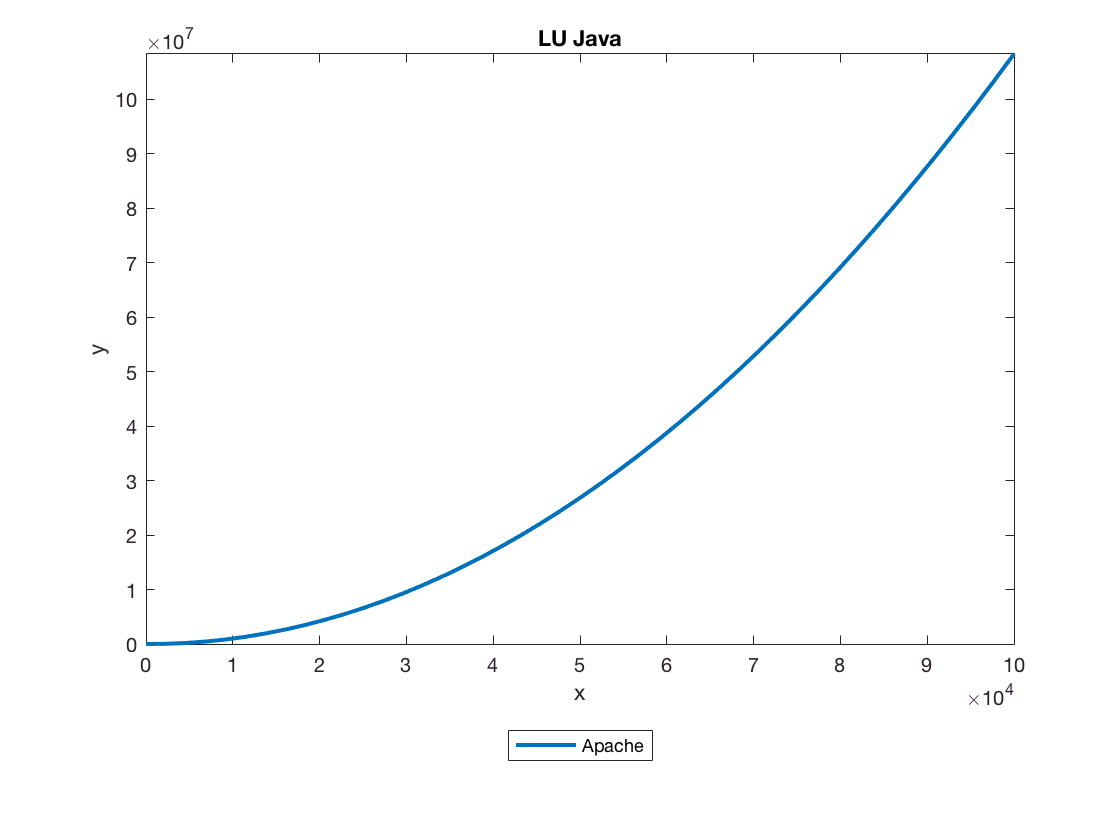

flipVector = flipud(resultVector);
polynom = poly2sym(flipVector);

G = GraphLogScale;
G.p = polynom;
G.f_plot2(0, 100000, 'LU Java', 'Apache', 'x', 'y')



ls2 = LeastSquare;
ls2.A = J(:,1);
ls2.b = J(:,2);
resultVector2 = ls2.solveLeastSquare(3);

start least square
Elapsed time is 0.000059 seconds.
Elapsed time is 0.000264 seconds.


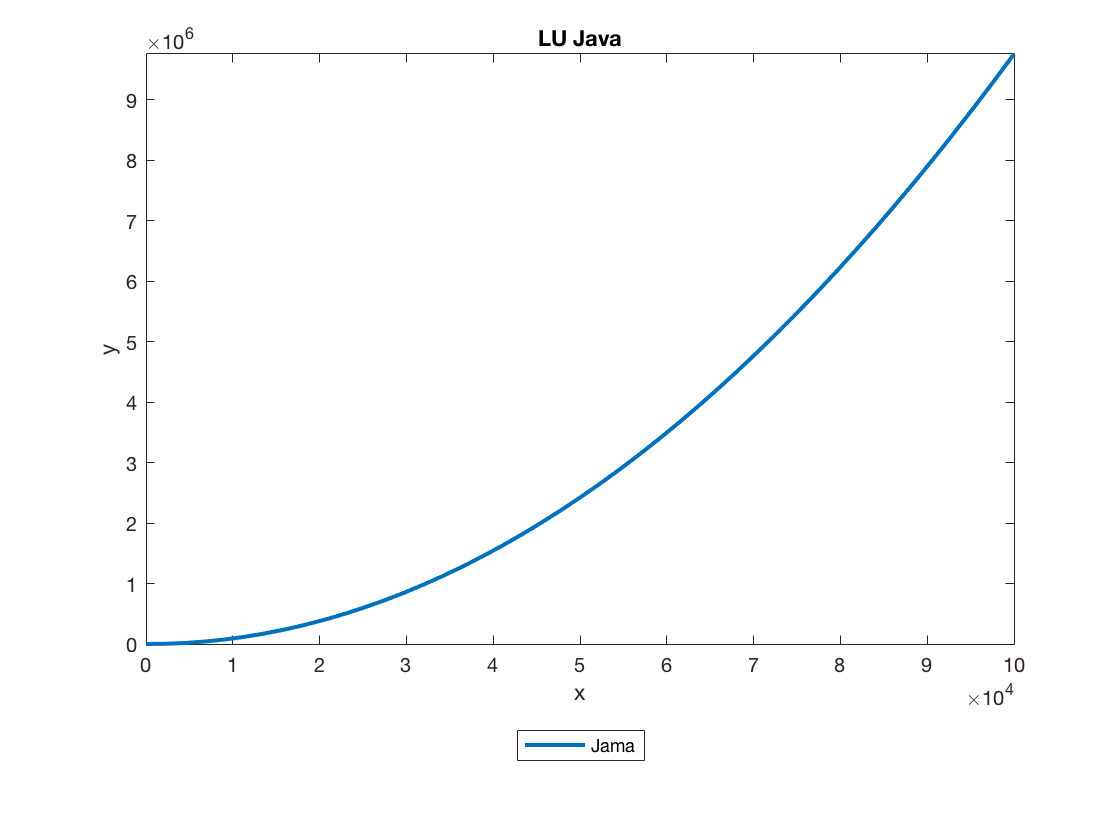

flipVector2 = flipud(resultVector2);
polynom2 = poly2sym(flipVector2);

G2 = GraphLogScale;
G2.p = polynom2;
G2.f_plot2(0, 100000, 'LU Java', 'Jama', 'x', 'y')


polyval(flipVector, 10000)

ans = 9.9360e+05

polyval(flipVector, 100000)

ans = 1.0833e+08


polyval(flipVector2, 10000)

ans = 9.1190e+04

polyval(flipVector2, 100000)

ans = 9.7566e+06


polyval(flipVector, 100)

ans = 462.0190

polyval(flipVector, 1000)

ans = 2.1847e+03


polyval(flipVector2, 100)

ans = 35.8876

polyval(flipVector2, 1000)

ans = 361.5323